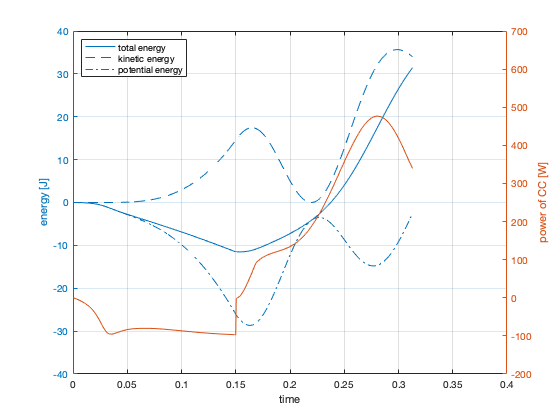

Fmax = 5500*sqrt(0.9+0.1*11); %最大筋力
Lopt = 0.055; %収縮要素の至適長
Lslack = 0.42; %弾性要素の自然長
Ksec = (0.9+0.1*11)*10^5; %弾性要素のバネ定数
mass = 70.0; %体重
Lcc0 = Lopt*0.7;
Lsec0 = Lslack + 2*mass*9.8 / Ksec;

width = 0.888;
c = -1/width^2;
Fiso0 = c*(Lcc0/Lopt)^2 - 2*c*Lcc0/Lopt + c + 1;

opts = odeset('RelTol', 1e-7, 'AbsTol', 1e-10, 'Event', 'dynEventFcn');
    %相対許容誤差を1e-5に抑える
    %x=0(離地)になった瞬間に計算終了

q0 = 2*mass*98/(Fmax*Fiso0);
ACTgene = ACT(11,:);

[t,y] = ode45(@(t,y) dynamics(t,y,ACTgene,Fmax,Lopt,Lslack,Ksec,mass),...
    [0,0.5], [0;-1e-10;2*mass*9.8/(Fmax*Fiso0);Lcc0; Lsec0], opts);
KE = 2*mass*y(:,1).^2;
PE = Ksec*(y(:,5)-Lsec0).^2/2-2*mass*9.8*(y(:,4)-Lcc0);
%PE = 2*mass*9.8*y(:,2);
%EE = Ksec*(y(:,5)-Lslack).^2/2;
W = KE + PE;
Pcc = -Ksec*(y(:,5)-Lslack).*[0;diff(y(:,4))./diff(t)];

figure;
yyaxis left
plot(t, W);
hold on
plot(t, KE);
plot(t, PE, '-.');
ylabel('energy [J]')
ylim([-40,40])
yyaxis right
plot(t, Pcc);
ylim([-200,700])
legend('total energy', 'kinetic energy', 'potential energy', 'location', 'northwest');
xlabel('time')
ylabel('power of CC [W]')
xlim([0,0.4])
grid on